% start digesting modelCalcium() in modelCalcium.m
%===================%===================%===================%

% set up parameters first
reconAlg = 'peeling';
fitonset = 0;
schmitt = [1.75, -1, 0.3];

ca_genmode = 'linDFF' ;

dur = 30;
offset = 1;

ca_amp1 = 0;
ca_tau1 = 0;
ca_rest = 50;
ca_amp = 7600;
ca_gamma = 400;
ca_kappas = 100;
ca_onsettau = 0.02;

A1 = 8.5;
A2 = 0;
tau1 = 0.5;
tau2 = 1.0;
tauOn = 0.01;
A1sigma = [];
tau1sigma = [];

snr = 5;
dffmax = 93;
frameRate = 30;
spikeRate = 0.2;
samplingRate = 1000;
recycleSpikeTimes=0;

kd = 250 ;
conc = 50000;
kappab = kd.*conc./(ca_rest+kd).^2 ;

doVectorized = 1;
cellNo=doVectorized;


dur = dur+offset;

x = 1/samplingRate:1/samplingRate:dur;
disp(length(x));

       31000



ca = zeros(cellNo,numel(x));
dff = zeros(cellNo,numel(x));

disp(size(ca));

           1       31000



spkTimes = cell(doVectorized,1); 
for n = 1:doVectorized
    %     poisson spike train
    spkTimes{n,1} = PoissonSpikeTrain(spikeRate(n),30+offset);
end

for n = 1:doVectorized
    spkTimes{n} = spkTimes{n} + offset;
end

spkTCell = spkTimes;

% line 56

ca_genmode = 'lindff' ; %'satDFF'
switch lower(ca_genmode)
    case 'lindff'
        disp('lindff');
        PeakA = A1 .* (tau1./tauOn.*(tau1./tauOn+1).^-(tauOn./tau1+1));

        % PeakA = A1 * 0.9063;
        % 0.9063 = 50 .* 51 .^ - 1.02
    
    case 'satdff'
        disp('satdff');
        ca_amp1=ca_amp./(1+ca_kappas+kappab);             % set for consistency
        ca_tau1=(1+ca_kappas+kappab)./ca_gamma;
        PeakCa = ca_amp1 + ca_rest;
        PeakDFF = Calcium2Fluor(PeakCa,ca_rest,kd,dffmax);
        PeakA = PeakDFF .* ...
            (ca_tau1./ca_onsettau.*(ca_tau1./ca_onsettau+1).^-(ca_onsettau./ca_tau1+1));
    
    otherwise
        error('Calcium trace generation mode illdefined');
end

lindff


sdnoise = PeakA./snr; 


% if linDFF
%disp(PeakA); %7.70313
%disp(sdnoise); %1.5406
%disp((tau1./tauOn.*(tau1./tauOn+1).^-(tauOn./tau1+1)));
%disp(tau1./tauOn);
%disp((tau1./tauOn+1));
%disp(tau1./tauOn.*(tau1./tauOn+1));
%disp((tauOn./tau1+1));

% if satDFF
% disp(PeakA);
% disp (ca_amp1);
% disp(ca_tau1);
% disp(PeakDFF);
% disp(PeakCa);
% disp(sdnoise);;


% line 76

spkTCell2 = cell(1,cellNo);
disp(size(spkTCell2));

     1     1




for m = 1:cellNo
    currentSpkT = spkTCell{m};
    if isempty(spkTCell{m})
        fprintf('No spikes for cell %1.0f. Skipping ...\n',m);
        if m == 1
            close all
            error('Must have spikes for cell 1. Try to increase firing rate / simulation duration.');
        end
        continue
    end

    if ~isempty(A1sigma) &&  ~isempty(tau1sigma)
        disp('gets into if');
        for n = 1:numel(currentSpkT)
            currentA1 = random('normal',A1(m),A1(m).*A1sigma);
            currentTau1 = random('normal',tau1(m),tau1(m).*tau1sigma);
            y = spkTimes2Calcium(currentSpkT(n),tauOn(m),currentA1,currentTau1,A2(m),...
                    tau2(m),samplingRate,dur);
            dff(m,:) = dff(m,:) + y(1:numel(x));
        end
    
    else
        disp('gets into else');
        switch lower(ca_genmode)
            case 'lindff'
                disp('  using lindff')
                % convolution over all spikes (faster, same model calcium transient)
                modelTransient = spkTimes2Calcium(0,tauOn(m),A1(m),tau1(m),A2(m),...
                    tau2(m),samplingRate,dur);
                spkVector = zeros(1,numel(x));
                for i = 1:numel(currentSpkT)
                    [~,idx] = min(abs(currentSpkT(i)-x));
                    spkVector(idx) = spkVector(idx)+1;
                end
                dffConv = conv(spkVector,modelTransient);
                dff(m,:) = dffConv(1:length(x));
            case 'satdff'
                disp('  using satdff')
                % taking saturation into account by solving the single comp model differential equation
                % piecewise, then applying nonlinear transformation from ca to dff
                ca = spkTimes2FreeCalcium(currentSpkT,S.ca_amp,S.ca_gamma,S.ca_onsettau,S.ca_rest, S.ca_kappas,...
                    S.kd, S.conc,S.samplingRate,dur);
                dff(m,:) = Calcium2Fluor(ca,S.ca_rest,S.kd,S.dffmax);
        end
    end
    currentSpkT = currentSpkT - offset;
    currentSpkT(currentSpkT<0) = [];
    spkTCell2{m} = currentSpkT;
    
end

gets into else


  using lindff


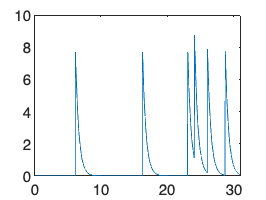


plot(x,dff(1,:));


spkTimes = spkTCell2;

disp(length(frameRate));

     1



subPlotNo = length(frameRate)+2;

axisHandles = [];


## DFF

     1



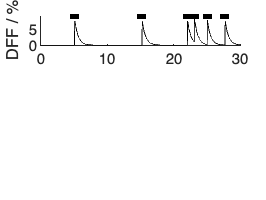

% line 130
%===================%===================%===================%
xPlot = x - offset;
dff(:,xPlot<0) = [];
xPlot(xPlot<0) = []; % looks like to remove first 1s data

cmap = lines(cellNo);
if cellNo == 1
    cmap = [0 0 0];
end

doPlot=1;
if doPlot
    subplot(subPlotNo,1,1)
    yOffset =0;
    for m = 1:cellNo
        disp(m)
        if isempty(spkTCell{m})
            continue
        end
        if m > 1
            currentDff = dff(m,:)+(yOffset-min(dff(m,:)));
        else
            currentDff = dff(m,:);
        end
        plot(xPlot,currentDff,'Color',cmap(m,:)); hold on
        yOffset = max(currentDff)+max(dff(:))/5;
        for n = 1:numel(spkTimes{m})
            h_err = errorbar(spkTimes{m}(n),max(currentDff),0,...
                max(dff(:))/10,'Color',cmap(m,:));
            removeErrorBarEnds(h_err)
            set(h_err,'LineWidth',2)
        end
    end
    set(gca,'ylim',[min(dff(:)) max(currentDff)+max(dff(:))/10],'box','off')
    axisHandles(1) = gca;
    ylabel('DFF / %');
end

## noisy DFF

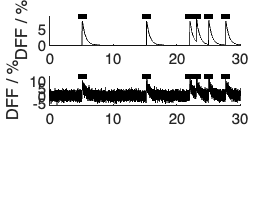

% line 162
%===================%===================%===================%
noisyDFF = zeros(cellNo,size(dff,2));
for m = 1:cellNo
    if isempty(spkTCell{m})
        continue
    end
    
    randomN = randn(1,size(dff,2));
    whiteNoise = sdnoise(m).*randn(1,size(dff,2));
    % it is possible to 'color' the noise, to mimick possible temporal autocorrelations (not
    % extensively tested)
    %     a = 0.99; % 0.99 gives auto-cov similar to exp. data
    % First Order Low pass filter y(n)=a*y(n-1)+(1-a)*x(n)
    % Filter Transfer function Y(Z) = X(Z)*(1-a)/(1-aZ^-1)
    %     coloredNoise = (filter(1-a,[1 -a],whiteNoise)) + whiteNoise;
    coloredNoise = whiteNoise;
    noisyDFF(m,:) = dff(m,:) + coloredNoise;
end
if doPlot
    subplot(subPlotNo,1,2)
    yOffset =0;
    for m = 1:cellNo
        if isempty(spkTCell{m})
            continue
        end
        if m > 1
            currentDff = noisyDFF(m,:)+(yOffset-min(noisyDFF(m,:)));
        else
            currentDff = noisyDFF(m,:);
        end
        plot(xPlot,currentDff,'Color',cmap(m,:)); hold on
        yOffset = max(currentDff)+max(noisyDFF(:))/5;
        for n = 1:numel(spkTimes{m})
            h_err = errorbar(spkTimes{m}(n),max(currentDff),0,...
                max(noisyDFF(:))/10,'Color',cmap(m,:));
            removeErrorBarEnds(h_err)
            set(h_err,'LineWidth',2)
        end
    end
    set(gca,'ylim',[min(noisyDFF(:)) ...
        max(currentDff)+max(noisyDFF(:))/10],'box','off')
    axisHandles(2) = gca;
    ylabel('DFF / %');
end

## noisy DFF at frame rate

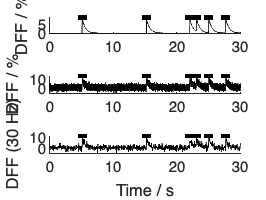

% line 207
%===================%===================%===================%
clear lowResT;
%lowResT = 1/frameRate:1/frameRate:max(xPlot);
lowResT = (1/frameRate:1/frameRate:max(xPlot)) - (0.5 .* 1/frameRate);
[~,idxList] = findClosest(lowResT,xPlot);
noisyDFFlowRes = zeros(m,numel(idxList));
for m = 1:cellNo
    if isempty(spkTCell{m})
        continue
    end
    noisyDFFlowRes(m,:) = noisyDFF(m,idxList);
end
if doPlot
    subplot(subPlotNo,1,3)
    yOffset = 0;
    for m = 1:cellNo
        if isempty(spkTCell{m})
            continue
        end
        if m > 1
            currentDff = noisyDFFlowRes(m,:)+(yOffset-min(noisyDFF(m,:)));
        else
            currentDff = noisyDFFlowRes(m,:);
        end
        plot(lowResT,currentDff,'Color',cmap(m,:)); hold on
        yOffset = max(currentDff)+max(noisyDFFlowRes(:))/5;
        for n = 1:numel(spkTimes{m})
            h_err = errorbar(spkTimes{m}(n),max(currentDff),0,...
                max(noisyDFFlowRes(:))/10,'Color',cmap(m,:));
            removeErrorBarEnds(h_err)
            set(h_err,'LineWidth',2)
        end
    end
    set(gca,'ylim',[min(noisyDFFlowRes(:)) ...
        max(currentDff)+max(noisyDFFlowRes(:))/10],'box','off')
    axisHandles(3) = gca;
    ylabel(sprintf('DFF (%1.0f Hz)',frameRate));
    xlabel('Time / s');
    linkaxes(axisHandles,'x')
end

dff = zeros(cellNo,length(noisyDFFlowRes));
for m = 1:cellNo
    if isempty(spkTCell{m})
        continue
    end
    % now perform baseline setting based on ratio of expected and real SD
    % of trace
    ratioSD = std(noisyDFFlowRes(m,:))./sdnoise(m);
    
    % empirical function describing baseperc as function of ratioSD
    basePerc = 50 - 50 / (1+exp(-(ratioSD-1-snr(m)*0.25)*10/snr(m)));

    baseValue = prctile(noisyDFFlowRes(m,:),basePerc);
    % sometimes it is better to specify the baseline explicitely, for example in cases of short
    % bursts of activity
    baseValue = 0;
    dff(m,:) = noisyDFFlowRes(m,:) - baseValue;
end

## Reconstruction

% line 274
%===================%===================%===================%
peelOptions.schmitt = [1.75 -1 0.3];
peelOptions.peel_p.optimizeSpikeTimes = 1;
peelOptions.peel_p.fitonset = 0;
peelOpts = peelOptions;

reconAlg='peeling';
spk_recmode = 'linDFF';
schmitt = peelOptions.schmitt

schmitt =     1.7500   -1.0000    0.3000



% switch lower(reconAlg)
%     case 'peeling'
%         [spikePredict, peel] = doPeel(dff, frameRate, ca_genmode, spk_recmode, A1, tau1, A2, ...
%                                       tau2,tauOn,ca_rest, ca_amp, ca_gamma, ca_onsettau, ...
%                                       ca_amp1,ca_tau1,ca_kappas, dffmax, kd, kappab, ...
%                                       sdnoise, peelOpts.schmitt, peelOpts.peel_p);
% end








